# 18 Time-Frequency Power and Baseline Normalizations

The purpose of this chapter is to discuss methods for converting time-frequency power data to a scale that is amenable to qualitative visual inspection and quantitative statistical analysis.

## 18.1 1/f Power Scaling

In many signals, including EEG, the frequency spectrum of data tends to show decreasing power at increasing frequencies which follows a “$1/f$” shape.

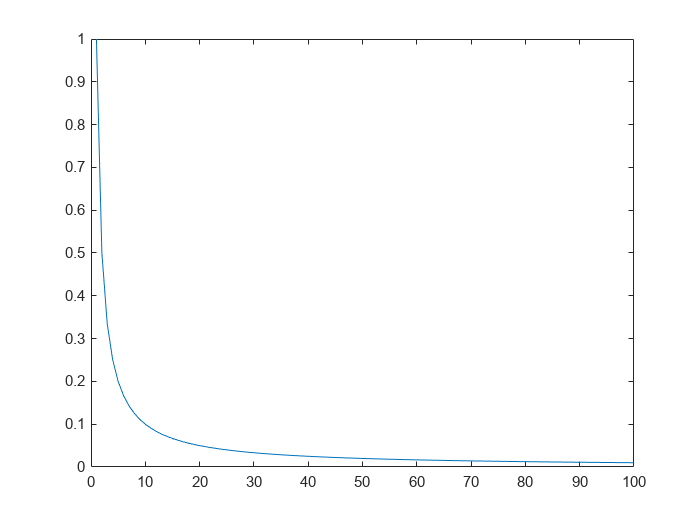

figure

c = 1;
x = 1;

plot(c./(1:100).^x)

**Figure 18.1**

*A 1/ f function that characterizes, among other things, EEG power data.*

The more general formula is: 

### 
$$P\left(f\right)=c/f^x$$


- $P\left(f\right)$ represents the power at a given frequency

- $c$ is a constant

- $f$ is the frequency

- $x$ is the exponent�

It is also called a power law, because one variable (in this case, EEG time-frequency power) is a power function of another variable (frequency).

The $1/f$ phenomenon entails five important limitations to interpreting and working with time-frequency power data: 

- It is difficult to visualize power across a large range of frequency bands.

- It is difficult to make quantitative comparisons of power across frequency bands.

- Aggregating effects across subjects can be difficult with raw power values.

- Task-related changes in power can be difficult to disentangle from background activity.

- Raw power values are not normally distributed because they cannot be negative and they are strongly positively skewed. This limits the ability to apply parametric statistical analyses to time-frequency power data.

There are methods that address some of these limitations. the 1/ f shape can be attenuated by: 

- Taking the logarithm of the power values

- Modeling the $1/f$ shape and removing that fitted function from the data

However, these methods do not address several of the other limitations discussed above.

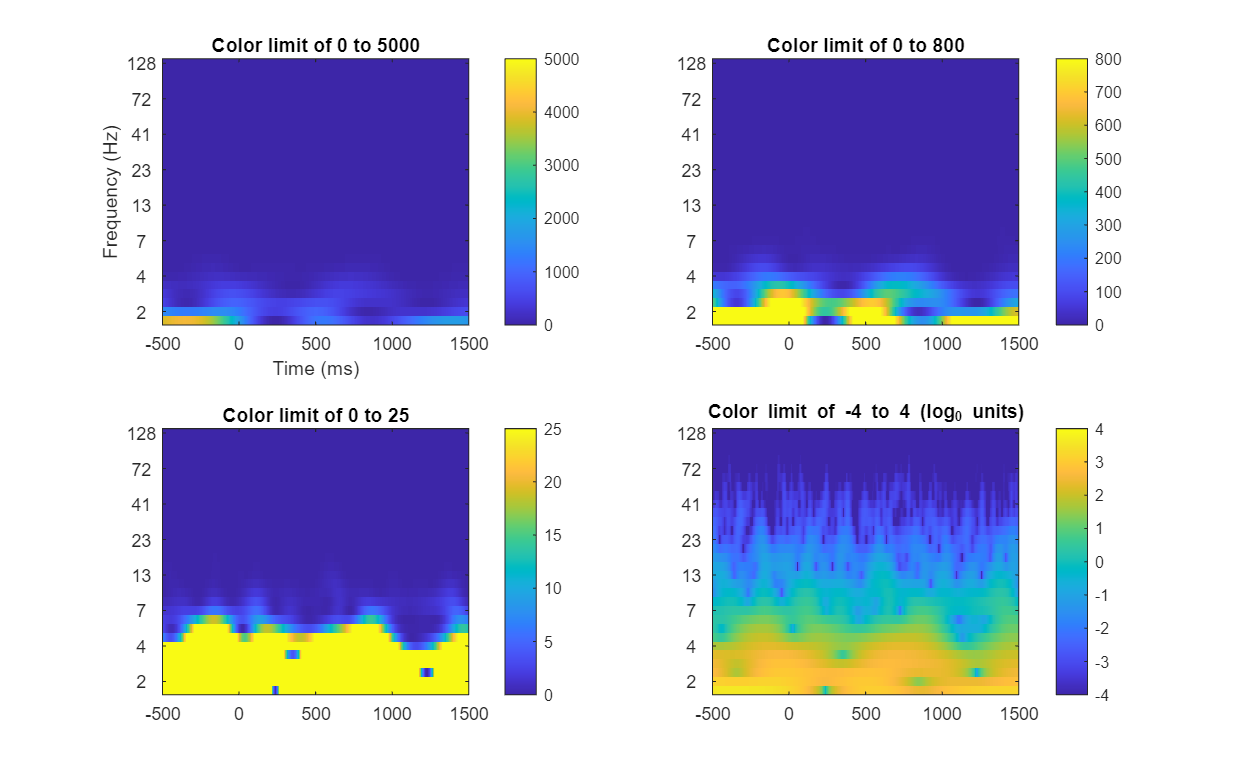

load sampleEEGdata

min_freq = 2;
max_freq = 128;
num_frex = 30;

frequencies = logspace(log10(min_freq),log10(max_freq),num_frex);
time = -1:1/EEG.srate:1;
half_of_wavelet_size = (length(time)-1)/2;

n_wavelet     = length(time);
n_data        = EEG.pnts;
n_convolution = n_wavelet+n_data-1;
n_conv_pow2   = pow2(nextpow2(n_convolution));
wavelet_cycles= 4; 

fft_data = fft(squeeze(EEG.data(23,:,1)),n_conv_pow2);

tf_data = zeros(length(frequencies),EEG.pnts);

for fi=1:length(frequencies)
    
    wavelet = (pi*frequencies(fi)*sqrt(pi))^-.5 * exp(2*1i*pi*frequencies(fi).*time) .* exp(-time.^2./(2*( wavelet_cycles /(2*pi*frequencies(fi)))^2))/frequencies(fi);
    fft_wavelet = fft(wavelet,n_conv_pow2);
    
    convolution_result_fft = ifft(fft_wavelet.*fft_data,n_conv_pow2);
    convolution_result_fft = convolution_result_fft(1:n_convolution); % note: here we remove the extra points from the power-of-2 FFT
    convolution_result_fft = convolution_result_fft(half_of_wavelet_size+1:end-half_of_wavelet_size);
    
    tf_data(fi,:) = abs(convolution_result_fft).^2;
end

ytickskip = 2:4:num_frex;
figure(Position=[100,100,800,500])

subplot(221)
imagesc(EEG.times,[],tf_data)
colorbar
set(gca,'ytick',ytickskip,'yticklabel',round(frequencies(ytickskip)),'ydir','normal','xlim',[-500 1500],'clim',[0 5000])
xlabel('Time (ms)'), ylabel('Frequency (Hz)')
title('Color limit of 0 to 5000')

subplot(222)
imagesc(EEG.times,[],tf_data)
colorbar
set(gca,'ytick',ytickskip,'yticklabel',round(frequencies(ytickskip)),'ydir','normal','xlim',[-500 1500],'clim',[0 800])
title('Color limit of 0 to 800')

subplot(223)
imagesc(EEG.times,[],tf_data)
colorbar
set(gca,'ytick',ytickskip,'yticklabel',round(frequencies(ytickskip)),'ydir','normal','xlim',[-500 1500],'clim',[0 25])
title('Color limit of 0 to 25')

subplot(224)
imagesc(EEG.times,[],log10(tf_data))
colorbar
set(gca,'ytick',ytickskip,'yticklabel',round(frequencies(ytickskip)),'ydir','normal','xlim',[-500 1500],'clim',[-4 4])
title('Color limit of -4 to 4 (log_1_0 units)')

**Figure 18.2**

*Time-frequency power plots showing that without any correction, no color scaling works optimally for all frequency bands.*

## 18.2 The Solution to 1/f Power in Task Designs

The solution is to use one of several kinds of baseline normalizations. All share four advantages:

- They transform all power data to the same scale.

- Because the normalizations are computed with respect to a (typically pretrial) baseline, task-related time-frequency dynamics become disentangled from background or task-unrelated dynamics.

- They put all power results into a common and easily numerically interpretable metric.

- Because baseline-normalized power data are often normally distributed, parametric statistical analyses may be appropriate to use.

## 18.3 Decibel Conversion

The decibel (dB) is a ratio between the strength of one signal (frequency-band-specific power) and the strength of another signal (a baseline level of power in that same frequency band):

### 
$$dB_{tf} =10\log_{10} \left(\frac{activity_{tf} }{\overline{baseline_f } }\right)$$


- The horizontal bar over baseline means the average baseline value across the baseline time period

- $t$ is time points

- $f$ is frequency points

Because the activity and the baseline within each frequency band are equally affected by $1/f$ scaling, any frequency-band-specific activity or amplitude level that is constant over time, including background activity, will be removed.

The baseline is a period of time, typically a few hundred milliseconds before the start of the trial, when little or no task-related processing is expected.

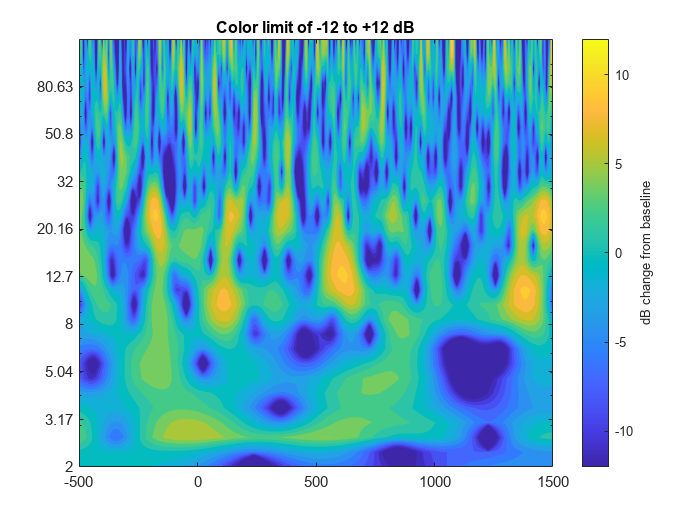

baselinetime = [ -500 -200 ];

[~,baselineidx(1)]=min(abs(EEG.times-baselinetime(1)));
[~,baselineidx(2)]=min(abs(EEG.times-baselinetime(2)));

baseline_power = mean(tf_data(:,baselineidx(1):baselineidx(2)),2);
dbconverted = 10*log10( bsxfun(@rdivide,tf_data,baseline_power));

figure
contourf(EEG.times,frequencies,dbconverted,40,'linecolor','none')
set(gca,'ytick',round(logspace(log10(frequencies(1)),log10(frequencies(end)),10)*100)/100,'yscale','log','xlim',[-500 1500],'clim',[-12 12])
colorbar
ylabel(colorbar,'dB change from baseline')
title('Color limit of -12 to +12 dB')

**Figure 18.3**

*Same time-frequency results that were shown in figure 18.2 but now decibel-transformed relative to a pretrial baseline period of – 500 to – 200 ms.*

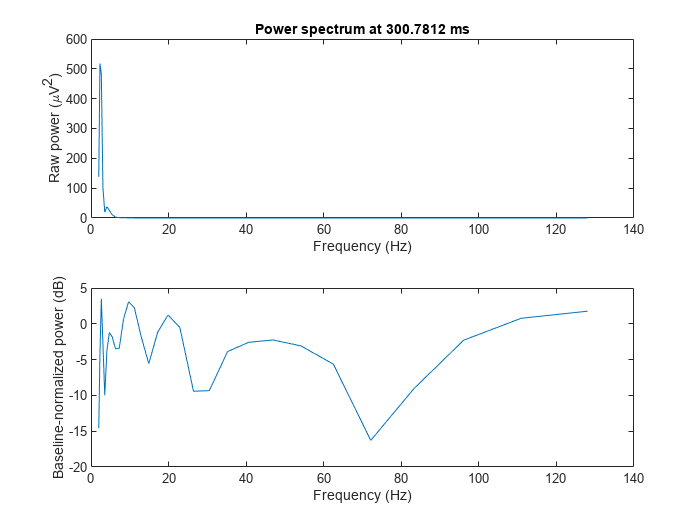

time2plot = 300;

[~,timeidx] = min(abs(EEG.times-time2plot));

figure
subplot(211)
plot(frequencies,tf_data(:,timeidx))
title([ 'Power spectrum at ' num2str(EEG.times(timeidx)) ' ms' ])
ylabel('Raw power (\muV^2)')
xlabel('Frequency (Hz)')
 
subplot(212)
plot(frequencies,dbconverted(:,timeidx))
ylabel('Baseline-normalized power (dB)')
xlabel('Frequency (Hz)')

**Figure 18.4**

*Comparison of raw and decibel-converted power at one time point. A horizontal line at 0 dB facilitates comparison of activity with respect to baseline power.*

Decibel conversion should be done on the trial-average power. That is, first average trials together and then transform to decibels.

In symmetric color scaling the minimum and maximum colors were mapped to the same magnitude below and above zero. Although there is no rule for how to set the color scaling, symmetric color scaling should be preferred in most situations. In some situations asymmetric color scaling is appropriate and can be used to highlight specific features of the time-frequency plots.

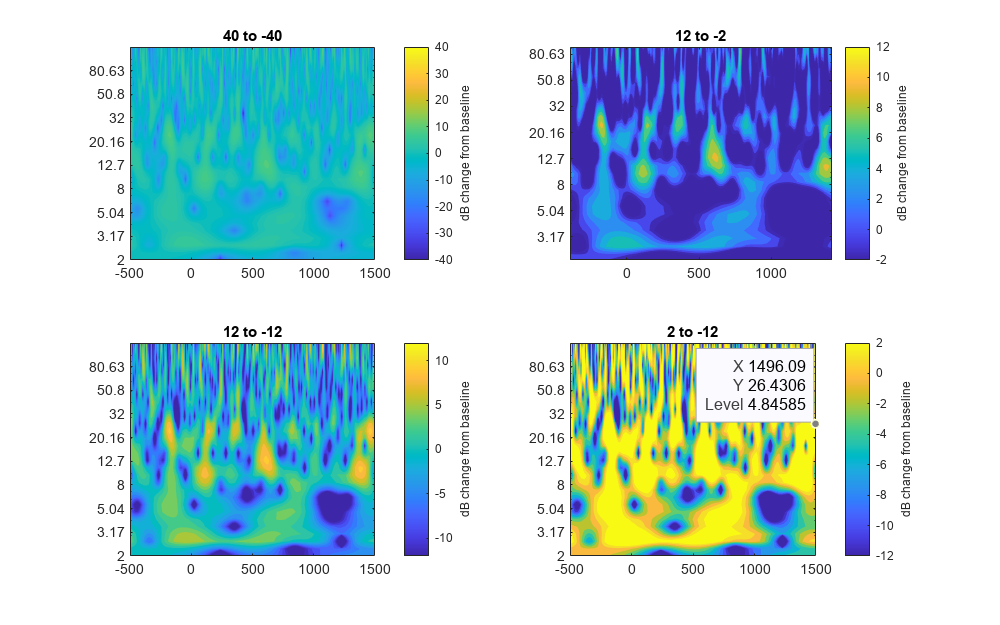

baselinetime = [ -500 -200 ];

[~,baselineidx(1)] = min(abs(EEG.times-baselinetime(1)));
[~,baselineidx(2)] = min(abs(EEG.times-baselinetime(2)));

baseline_power = mean(tf_data(:,baselineidx(1):baselineidx(2)),2);
dbconverted = 10*log10(bsxfun(@rdivide,tf_data,baseline_power));

figure(Position=[100,100,800,500])

subplot(2,2,1)
contourf(EEG.times,frequencies,dbconverted,40,'linecolor','none')
set(gca,'ytick',round(logspace(log10(frequencies(1)),log10(frequencies(end)),10)*100)/100,'yscale','log','xlim',[-500 1500],'clim',[-40 40])
cb1 = colorbar;
ylabel(cb1,'dB change from baseline')
title('40 to -40')

subplot(2,2,2)
contourf(EEG.times,frequencies,dbconverted,40,'linecolor','none')
set(gca,'ytick',round(logspace(log10(frequencies(1)),log10(frequencies(end)),10)*100)/100,'yscale','log','xlim',[-500 1500],'clim',[-2 12])
cb2 = colorbar;
ylabel(cb2,'dB change from baseline')
title('12 to -2')

subplot(2,2,3)
contourf(EEG.times,frequencies,dbconverted,40,'linecolor','none')
set(gca,'ytick',round(logspace(log10(frequencies(1)),log10(frequencies(end)),10)*100)/100,'yscale','log','xlim',[-500 1500],'clim',[-12 12])
cb3 = colorbar;
ylabel(cb3,'dB change from baseline')
title('12 to -12')

subplot(2,2,4)
contourf(EEG.times,frequencies,dbconverted,40,'linecolor','none')
set(gca,'ytick',round(logspace(log10(frequencies(1)),log10(frequencies(end)),10)*100)/100,'yscale','log','xlim',[-500 1500],'clim',[-12 2])
cb4 = colorbar;
ylabel(cb4,'dB change from baseline')
title('2 to -12')

**Figure 18.5**

*Different color scaling applied to the same time-frequency power results.*

## 18.4 Percentage Change and Baseline Division

Percentage change is another option for baseline normalization. Similar to decibels, after percentage change, the results must be interpreted as changes in power relative to the power during the baseline period.

### 
$$prctchange_{tf} =\frac{activity_{tf} -\overline{baseline_f } }{\overline{baseline_f } }100$$


A related transform to percentage change is dividing power during the task by power during the baseline time period. The unit is a ratio and is a linear transform of percentage change.

## 18.5 Z-Transform

With the Z-transform, power data are scaled to standard deviation units relative to the power data during the baseline period. The units are normal Z values and so can be easily interpreted and converted to p values.


$$Z_{tf} =\frac{activity_{tf} -\overline{baseline_f } }{\sqrt{n^{-1} \sum_{t=1}^n (baseline_{\mathrm{tf}} -\overline{baseline_f } )^2 }}$$


- $n$ is the number of time points in the baseline period

- The denominator is the formula for the standard deviation

Z-transform is based both on the average baseline power and on the standard deviation of the baseline power over time.

## 18.6 Not All Transforms Are Equal

Different baseline transformations should yield similar but not necessarily identical results. 

An important difference between decibel and percentage change, for example, is that decibels provide a logarithmic scale, whereas percentage change is a linear scale. At decibel and percentage change values near zero, both transforms will give highly similar results because at this small scale, decibels approach a linear function. As the values become further away from zero, however, the scales begin to differ.

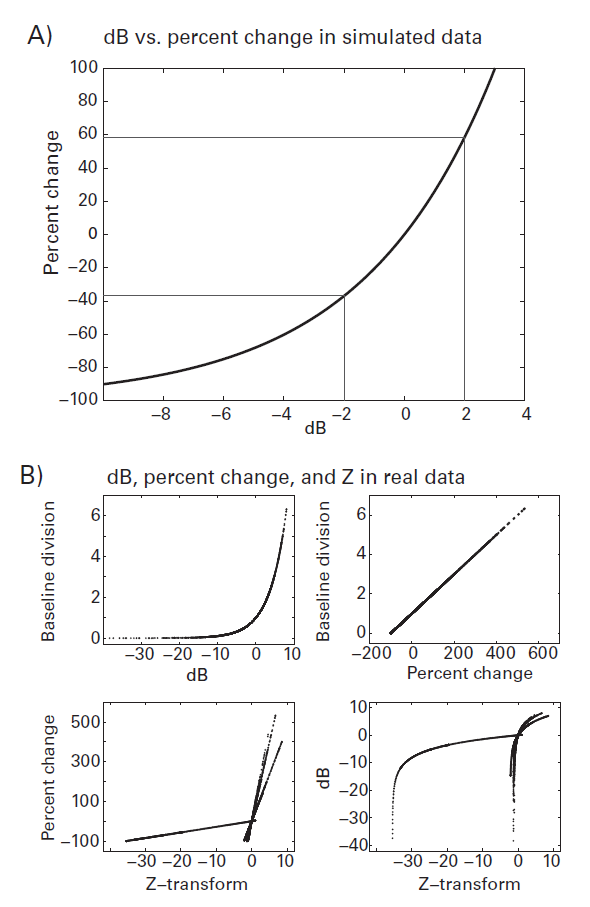

**Figure 18.6**

*Comparisons of different time-frequency power baseline normalization methods.*

The Z-transform, however, has a more complex relationship to decibel and percentage change that cannot be analytically derived because it depends on the characteristics of the data. This is because the Z-transform is influenced by the standard deviation of power data during the baseline period.

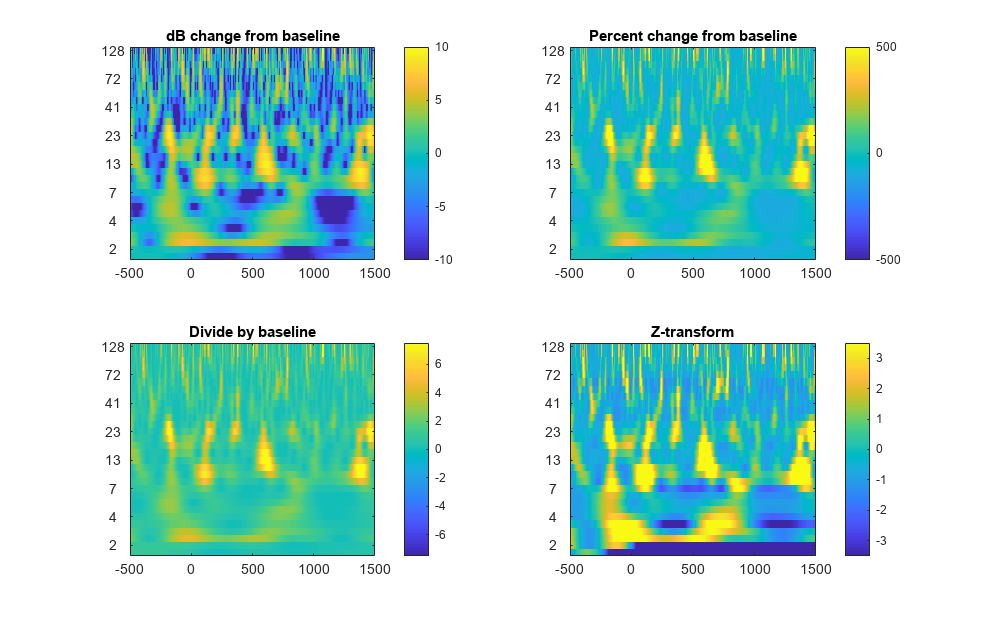

activity = 1:.01:20;
baseline = 10;

db = 10*log10(activity./ baseline );
pc = 100*( activity-baseline)./ baseline;

[~,dbOf2]=min(abs(db-2));
[~,dbOfminus2]=min(abs(db--2));

baseline_power = mean(tf_data(:,baselineidx(1):baselineidx(2)),2);
pctchange = 100 * (tf_data-repmat(baseline_power,1,EEG.pnts))./ repmat(baseline_power,1,EEG.pnts);

baselinediv = tf_data ./ repmat(baseline_power,1,EEG.pnts);

baseline_power = tf_data(:,baselineidx(1):baselineidx(2));
baselineZ = (tf_data-repmat(mean(baseline_power,2),1,size(tf_data,2))) ./ repmat(std(baseline_power,[],2),1,size(tf_data,2));

figure(Position=[100,100,800,500])

subplot(221)
imagesc(EEG.times,[],dbconverted)
colorbar
set(gca,'ytick',ytickskip,'yticklabel',round(frequencies(ytickskip)),'ydir','normal','xlim',[-500 1500],'clim',[-10 10])
title('dB change from baseline')

subplot(222)
imagesc(EEG.times,[],pctchange)
colorbar
set(gca,'ytick',ytickskip,'yticklabel',round(frequencies(ytickskip)),'ydir','normal','xlim',[-500 1500],'clim',[-500 500])
title('Percent change from baseline')

subplot(223)
imagesc(EEG.times,[],baselinediv)
colorbar
set(gca,'ytick',ytickskip,'yticklabel',round(frequencies(ytickskip)),'ydir','normal','xlim',[-500 1500],'clim',[-7.5 7.5])
title('Divide by baseline')

subplot(224)
imagesc(EEG.times,[],baselineZ)
colorbar
set(gca,'ytick',ytickskip,'yticklabel',round(frequencies(ytickskip)),'ydir','normal','xlim',[-500 1500],'clim',[-3.5 3.5])
title('Z-transform')

**Figure 18.7**

*Results from the same data and same analysis, but with different baseline normalization methods applied.*

## 18.7 Other Transforms

Other transforms could be based on: 

- Empirical mode decomposition

- Frobenius norm 

- Other matrix norms

Although it is best to use a normalization approach that is commonly used, any procedure that is equally applied to all conditions, electrodes, and subjects, and that addresses the limitations of raw power discussed above, could be justifiable. For time-frequency power, linear baseline subtractions should be avoided because they do not address $1/f$ power-law scaling.

## 18.8 Mean versus Median

The typical strategy for aggregating activity over many trials is to compute the average, or the arithmetic mean. 

There are two related reasons why the mean across trials may be inappropriate in some situations:

- Power values cannot be negative, which means that the distribution of power values across trials is likely to be positively skewed.

- For the same reason, outliers and other nonrepresentative data are more likely to be larger than the mean, compared to smaller than the mean, and therefore will bias the mean toward larger values. This is further exacerbated by the fact that power is amplitude squared.

Computing the median is an acceptable alternative to the mean for some non-Gaussian or skewed distributions, particularly in situations in which outliers may influence the mean. If the data are clean, there are no outliers, and there is a sufficient number of trials, mean and median should give similar results.

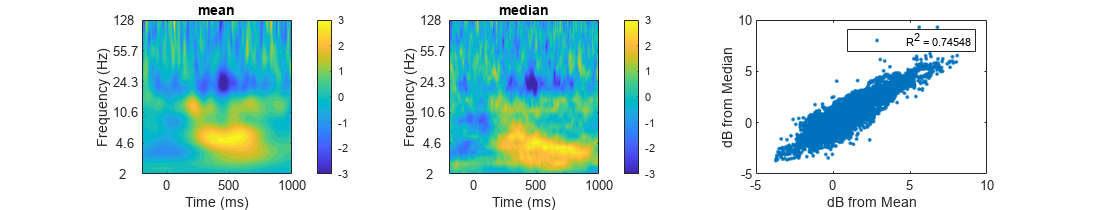

chan2plot = 'fcz';
baselinetime = [ -500 -200 ];

[~,baselineidx(1)] = min(abs(EEG.times-baselinetime(1)));
[~,baselineidx(2)] = min(abs(EEG.times-baselinetime(2)));

tf_data = zeros(2,length(frequencies),EEG.pnts);

n_data        = EEG.pnts*EEG.trials;
n_convolution = n_wavelet+n_data-1;
n_conv_pow2   = pow2(nextpow2(n_convolution));

fft_data = fft(reshape(EEG.data(strcmpi(chan2plot,{EEG.chanlocs.labels}),:,:),1,[]),n_conv_pow2);

for fi=1:length(frequencies)
    
    wavelet = (pi*frequencies(fi)*sqrt(pi))^-.5 * exp(2*1i*pi*frequencies(fi).*time) .* exp(-time.^2./(2*( wavelet_cycles /(2*pi*frequencies(fi)))^2))/frequencies(fi);
    fft_wavelet = fft(wavelet,n_conv_pow2);
    
    convolution_result_fft = ifft(fft_wavelet.*fft_data,n_conv_pow2);
    convolution_result_fft = convolution_result_fft(1:n_convolution);
    convolution_result_fft = convolution_result_fft(half_of_wavelet_size+1:end-half_of_wavelet_size);
    convolution_result_fft = reshape(convolution_result_fft,EEG.pnts,EEG.trials);
    
    if fi==6
        convdat2keep = convolution_result_fft;
    end
    
    tf_data(1,fi,:) = mean(abs(convolution_result_fft).^2,2);
    tf_data(2,fi,:) = median(abs(convolution_result_fft).^2,2);
end

labelz = {'mean';'median'};
figure(Position=[100,100,1300,250])
for i=1:2
    baseline_power = squeeze(mean(tf_data(i,:,baselineidx(1):baselineidx(2)),3));
    dbconverted = 10*log10( squeeze(bsxfun(@rdivide,tf_data(i,:,:),baseline_power) ));
    
    subplot(1,3,i)
    contourf(EEG.times,frequencies,dbconverted,40,'linecolor','none')
    colorbar
    set(gca,'clim',[-3 3],'xlim',[-200 1000],'yscale','log','ytick',logspace(log10(frequencies(1)),log10(frequencies(end)),6),'yticklabel',round(logspace(log10(frequencies(1)),log10(frequencies(end)),6)*10)/10)
    title(labelz{i}), ylabel('Frequency (Hz)'), xlabel('Time (ms)')
end

subplot(133)
db_mean = 10*log10( bsxfun(@rdivide,tf_data(1,:,:),mean(tf_data(1,:,baselineidx(1):baselineidx(2)),3)));
db_medn = 10*log10( bsxfun(@rdivide,tf_data(2,:,:),mean(tf_data(2,:,baselineidx(1):baselineidx(2)),3)));
plot(db_mean(:),db_medn(:),'.')
r=corr(db_mean(:),db_medn(:));
legend([ 'R^2 = ' num2str(r*r) ])
xlabel('dB from Mean')
ylabel('dB from Median')

**Figure 18.8**

*Time-frequency power plots of the same data using mean (panel A) or median (panel B) to combine data across trials. Panel C shows the correlation between the results using mean and using median.*

The mean and median provide very similar results. But visual inspection of the time-frequency plots may suggests some differences. Of course, these differences are based on visual qualitative inspectionand characteristics of the data.

The performance of the mean and median can be compared in the presence of an artificially created outlier.

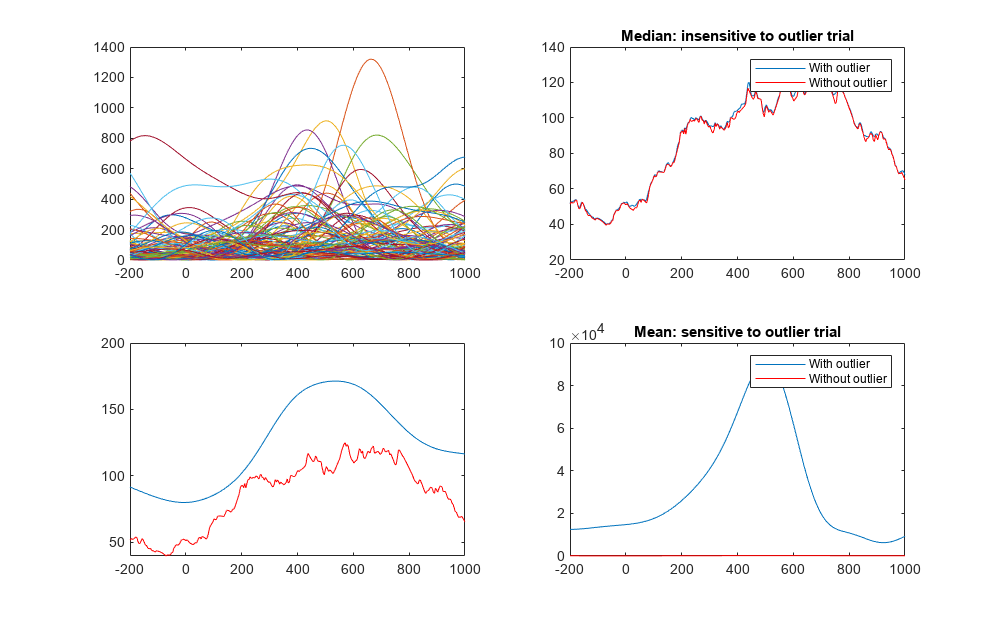

figure(Position=[100,100,800,500])

subplot(221)
plot(EEG.times,abs(convdat2keep).^2)
set(gca,'xlim',[-200 1000])
subplot(223)
plot(EEG.times,mean(abs(convdat2keep).^2,2))
hold on
plot(EEG.times,median(abs(convdat2keep).^2,2),'r')
set(gca,'xlim',[-200 1000])

convdat2keep(:,100) = convdat2keep(:,10)*100;

subplot(222)
plot(EEG.times,median(abs(convdat2keep).^2,2))
hold on
plot(EEG.times,median(abs(convdat2keep(:,1:end-1)).^2,2),'r')
set(gca,'xlim',[-200 1000])
legend({'With outlier';'Without outlier'})
title('Median: insensitive to outlier trial')

subplot(224)
plot(EEG.times,mean(abs(convdat2keep).^2,2))
hold on
plot(EEG.times,mean(abs(convdat2keep(:,1:end-1)).^2,2),'r')
set(gca,'xlim',[-200 1000])
legend({'With outlier';'Without outlier'})
title('Mean: sensitive to outlier trial')

**Figure 18.9**

*Comparing the performance of the mean and median in the presence of an artificially created outlier.*

The mean is most commonly used in the cognitive electrophysiology literature and is likely to be appropriate in most situations in which there are clean data and a sufficient number of trials. One situation in which the median might be preferred over the mean, or in addition to the mean, is when there are few trials and noisy data.

## 18.9 Single-Trial Baseline Normalization

Typically, power data are averaged across all trials, and then a baseline normalization is applied. Performing baseline normalization on single trials prior to averaging helps minimize the influence of outlier trials but does not completely mitigate their impact, particularly for large outliers. The single-trial Z-transform helps to minimize the impact of the outlier but still provides a somewhat positively skewed representation of the central tendency of power fluctuations. One potential limitation of the single-trial Z-transformation is that noisy single-trial baseline periods may lead to nonrepresentative estimates of power fluctuations.

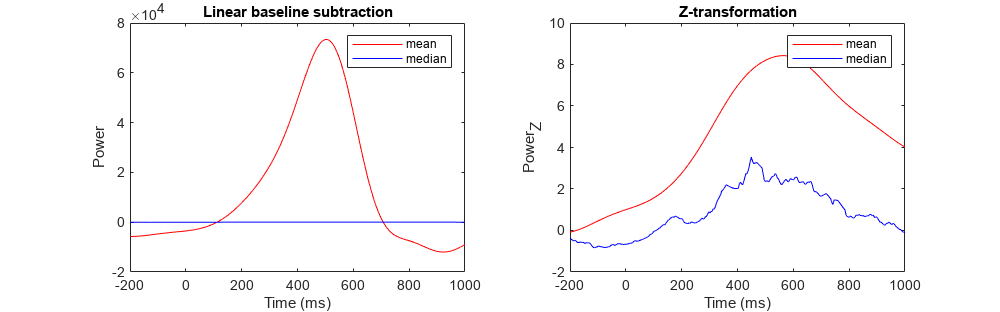

convdatPower  = abs(convdat2keep).^2;

convdat2keepB = convdatPower - repmat(mean(convdatPower(baselineidx(1):baselineidx(2),:),1),size(convdatPower,1),1);

convdat2keepZ = (convdatPower - repmat(mean(convdatPower(baselineidx(1):baselineidx(2),:),1),size(convdatPower,1),1)) ./ repmat(std(convdatPower(baselineidx(1):baselineidx(2),:)),size(convdatPower,1),1);

convdat2keepL = log10(convdatPower);

figure(Position=[100,100,800,250])

subplot(121)
plot(EEG.times,mean(convdat2keepB,2),'r')
hold on
plot(EEG.times,median(convdat2keepB,2),'b')
xlabel('Time (ms)'), ylabel('Power')
set(gca,'xlim',[-200 1000])
title('Linear baseline subtraction'),legend({'mean';'median'})

subplot(122)
plot(EEG.times,mean(convdat2keepZ,2),'r')
hold on
plot(EEG.times,median(convdat2keepZ,2),'b')
xlabel('Time (ms)'), ylabel('Power_Z')
set(gca,'xlim',[-200 1000])
title('Z-transformation'),legend({'mean';'median'})

**Figure 18.10**

*Comparison of mean and median power after linear baseline subtraction (left) and single-trial Z-transform (right), in the presence of an outlier trial.*

## 18.10 The Choice of Baseline Time Window

Because baseline normalization means that activity is rescaled to be relative to the activity during the baseline period, the choice of baseline time period is an important one that may have implications for the results

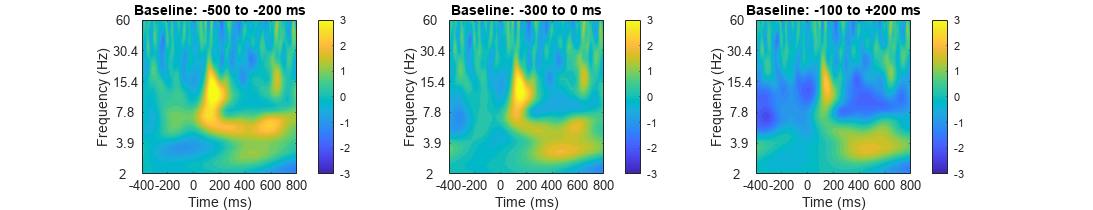

chan2plot = 'p1';

min_freq = 2;
max_freq = 60;
num_frex  = 30;
frequencies = logspace(log10(min_freq),log10(max_freq),num_frex);
time = -1:1/EEG.srate:1;
half_of_wavelet_size = (length(time)-1)/2;
wavelet_cycles = 4;

n_wavelet     = length(time);
n_data        = EEG.pnts*EEG.trials;
n_convolution = n_wavelet+n_data-1;
n_conv_pow2   = pow2(nextpow2(n_convolution));

fft_data = fft(reshape(EEG.data(strcmpi(chan2plot,{EEG.chanlocs.labels}),:,:),1,[]),n_conv_pow2);

tf_data = zeros(length(frequencies),EEG.pnts);

for fi = 1:length(frequencies)
    wavelet = (pi*frequencies(fi)*sqrt(pi))^-.5 * exp(2*1i*pi*frequencies(fi).*time) .* exp(-time.^2./(2*(wavelet_cycles/(2*pi*frequencies(fi)))^2))/frequencies(fi);
    fft_wavelet = fft(wavelet,n_conv_pow2);
    convolution_result_fft = ifft(fft_wavelet.*fft_data,n_conv_pow2);
    convolution_result_fft = convolution_result_fft(1:n_convolution);
    convolution_result_fft = convolution_result_fft(half_of_wavelet_size+1:end-half_of_wavelet_size);
    convolution_result_fft = reshape(convolution_result_fft,EEG.pnts,EEG.trials);
    tf_data(fi,:) = mean(abs(convolution_result_fft).^2,2);
end

baselines = {
    [-500 -200]
    [-300 0]
    [-100 200]
};

titlestr = {
    'Baseline: -500 to -200 ms'
    'Baseline: -300 to 0 ms'
    'Baseline: -100 to +200 ms'
};

figure(Position=[100,100,1300,250])

for bi = 1:3
    baselinetime = baselines{bi};
    [~,baselineidx(1)] = min(abs(EEG.times-baselinetime(1)));
    [~,baselineidx(2)] = min(abs(EEG.times-baselinetime(2)));
    baseline_power = mean(tf_data(:,baselineidx(1):baselineidx(2)),2);
    dbconverted = 10*log10(bsxfun(@rdivide,tf_data,baseline_power));

    subplot(1,3,bi)
    contourf(EEG.times,frequencies,dbconverted,40,'linecolor','none')
    colorbar
    set(gca,'yscale','log','xlim',[-400 800],'clim',[-3 3], ...
        'ytick',logspace(log10(frequencies(1)),log10(frequencies(end)),6), ...
        'yticklabel',round(logspace(log10(frequencies(1)),log10(frequencies(end)),6)*10)/10)
    title(titlestr{bi})
    ylabel('Frequency (Hz)')
    xlabel('Time (ms)')
end

**Figure 18.11**

*The choice of baseline time period used for power normalization has implications for interpreting the results.*

Although in ERP analyses it is common to have the baseline end at time = 0, for time-frequency analyses this can be suboptimal because temporal smoothing from time-frequency decomposition can produce some temporal leakage of trial-related activity to the pretrial time period, particularly if the activity occurs shortly after the time = 0 event. Thus, a good baseline time period might be – 500 to – 200 ms, or – 400 to – 100 ms.

Your choice of baseline time period also depends on what happened prior to time = 0.

Because any activity present in the baseline period will be transferred to the task-related activity, it is a good idea to use the pretrial period as a baseline even if you are not examining stimulus-locked activity.

A baseline period of a few hundreds of milliseconds prior to trial onset is the most common time period. Power in those 300 ms reflects activity from a wider window of time in which the activity within those 300 ms is maximally weighted.

A pretrial baseline period is optimal. Whenever possible, try to design your experiment such that a pretrial baseline period of several hundred milliseconds can be used. However, this might not always be possible; some experiment designs may preclude using a pretrial baseline period. This might happen, for example, if you have rapidly presented trials and thus insufficient time for a clean baseline period.

There are three alternative options for baseline normalization that you could consider:

- To use a separate rest period as the baseline. This could be a break of several tens of seconds every few minutes or after a block of trials. However, keep in mind that differences in cognitive mindset between task performance and a long resting baseline period might make the rest period an inappropriate baseline as a comparison for phasic task-related activity. 

- To use a control condition as the baseline. The potential danger with this approach is that if the timing of events differs between the conditions, condition differences may become difficult to interpret.

- To use the time series from the entire trial as the baseline. This approach is appropriate for detecting phasic changes in activity. However, sustained changes in power throughout the trial period may become difficult to detect.

**Condition-specific baseline:** means that each condition is baseline-normalized independently of all other conditions.

**Condition-average baseline:** means that the conditions are first averaged together, then the baseline activity is computed, and then that average baseline activity is applied to each condition. 

There are two advantages of the condition-average baseline. 

- The signal-to-noise ratio of the baseline power will increase because more trials will be included in the average.

- Any condition differences in baseline activity will be retained, which is advantageous if you have hypotheses about condition differences in pretrial activity.

## 18.11 Disadvantages of Baseline-Normalized Power

The main disadvantage of the baseline normalizations is that the activity becomes relative to the activity during the baseline period. This has two implications: 

- Zero activity means that there is no difference in activity compared to the baseline time period you selected; 

- Activity that occurs during the baseline period becomes inversely reflected as task-related activity.

These disadvantages should be considered alongside the advantages of baseline normalization, namely that data from all conditions, electrodes, frequencies, and subjects are on the same scale and are thus visually and quantitatively comparable. 

Baseline normalization is almost always a good idea but is not always necessary.

Finally, note that the conversions discussed in this chapter can be applied to any data, not only time-frequency power. However, decibels cannot be used on data that can have zero or negative values.

## 18.12 Signal-to-Noise Estimates

Signal-to-noise ratio (SNR) is a useful although not commonly used measure of the quality of the data. To compute the true SNR, you need to be able to dissociate the signal from the noise. In real EEG data this is not possible because signal and noise are mixed together. Thus, SNR can be estimated as the ratio of the mean signal to the standard deviation of the signal.

### 
$$SNR=\frac{\mu }{\sigma }$$


For time-frequency data, SNR can be computed over time and frequency:

### 
$$SNR_{tf} =\frac{\mu_{tf} }{\sigma_{tf} }$$


- $\mu$ is the mean power over trials

- $\sigma$ is the standard deviation of the power over trials

- $tf$ indicates one time-frequency point. 

Alternatively, you can compute SNR base, which is the power at each time-frequency point relative to the variance in the pretrial baseline period.

With ERPs, SNR is often defined as the peak of a trial-averaged component (e.g., the P3) compared to the temporal variance during the baseline period (e.g., – 200 ms to trial onset). A comparable analysis on trial-averaged time-frequency SNR estimates of up to 100, which is an order of magnitude larger than the range typically reported for SNR of ERP components. Likewise, computing the time course of the ERP SNR in the same way that SNR was computed in trial-averaged time-frequency SNR values of around 0.1 for the ERP. This can be compared to average values of around 0.8 for time-frequency power.

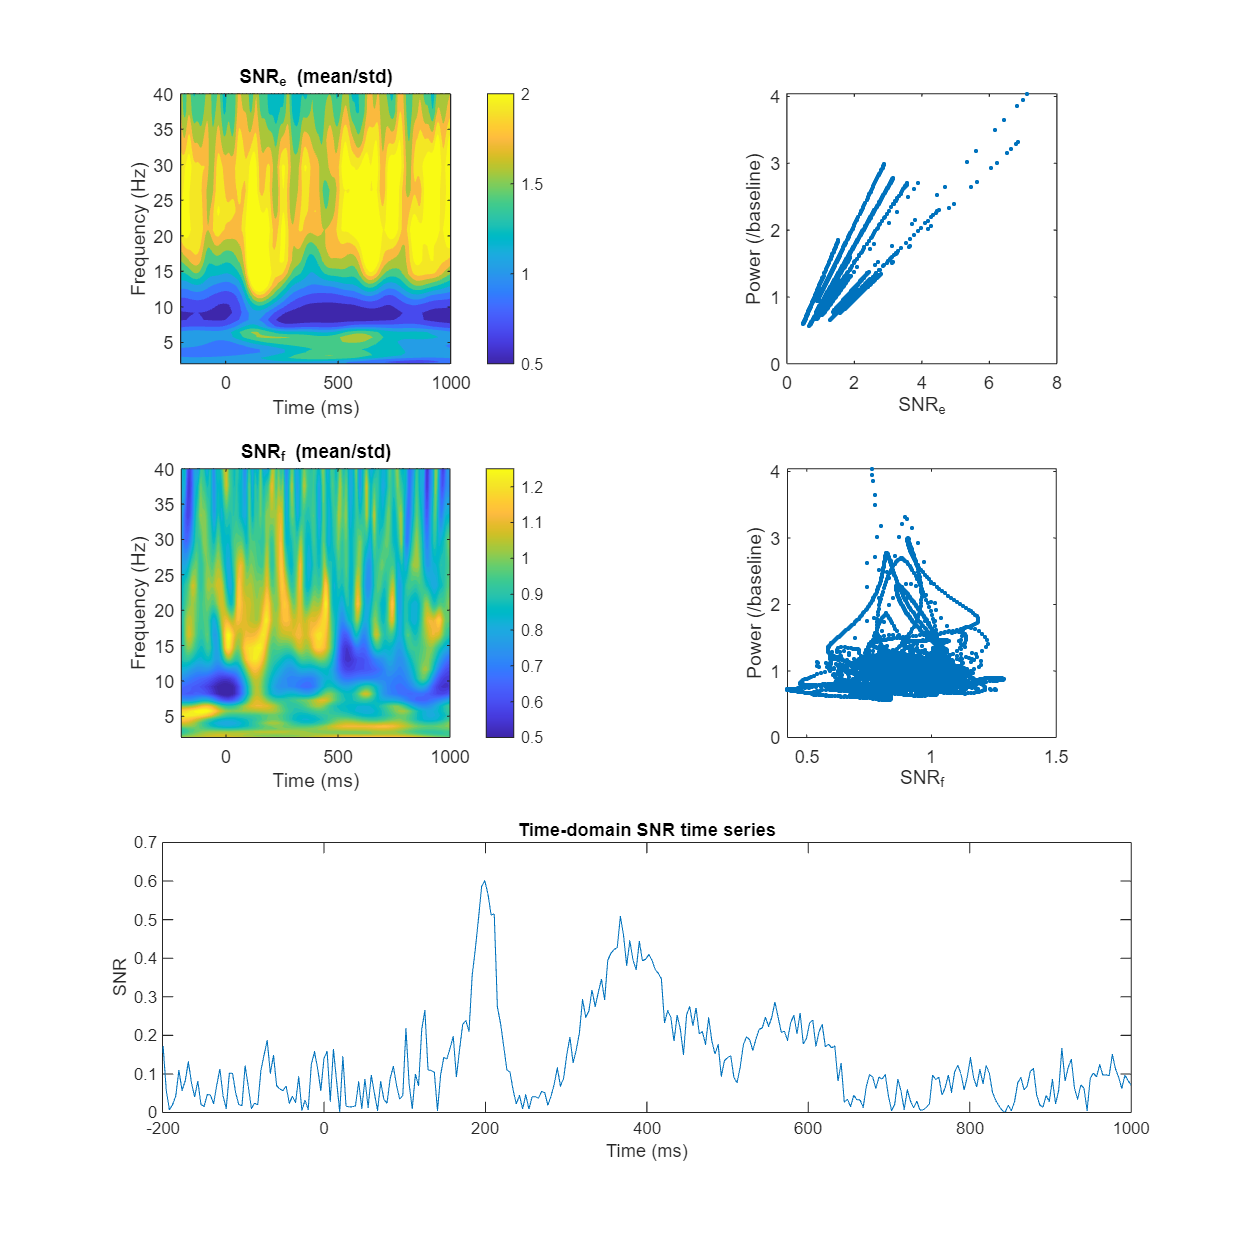

snr_bs = zeros(length(frequencies),EEG.pnts);
snr_tf = zeros(length(frequencies),EEG.pnts);
tf     = zeros(length(frequencies),EEG.pnts);

for fi=1:length(frequencies)
    
    wavelet = exp(2*1i*pi*frequencies(fi).*time) .* exp(-time.^2./(2*( wavelet_cycles /(2*pi*frequencies(fi)))^2))/frequencies(fi);
    fft_wavelet = fft(wavelet,n_conv_pow2);
    
    convolution_result = ifft(fft_wavelet.*fft_data,n_conv_pow2) * sqrt(wavelet_cycles /(2*pi*frequencies(fi)));
    convolution_result = convolution_result(1:n_convolution);
    convolution_result = convolution_result(half_of_wavelet_size+1:end-half_of_wavelet_size);
    convolution_result = reshape(convolution_result,EEG.pnts,EEG.trials);
    
    snr_tf(fi,:) = mean(abs(convolution_result).^2,2)./std(abs(convolution_result).^2,[],2);
    snr_bs(fi,:) = mean(abs(convolution_result).^2,2)./std(mean(abs(convolution_result(baselineidx(1):baselineidx(2),:)).^2,1),[],2);
    
    tf(fi,:) = mean(abs(convolution_result).^2,2);
    
end

figure(Position=[100,100,800,800])
subplot(321)
contourf(EEG.times,frequencies,snr_bs,40,'linecolor','none')
colorbar
set(gca,'clim',[.5 2],'xlim',[-200 1000],'ylim',[frequencies(1) 40])
title('SNR_b_a_s_e_l_i_n_e (mean/std)'), ylabel('Frequency (Hz)'), xlabel('Time (ms)')
axis square

subplot(322)

baseline_power = mean(tf(:,baselineidx(1):baselineidx(2)),2);
baselinediv    = tf ./ repmat(baseline_power,1,EEG.pnts);

plot(snr_bs(1:3:end),baselinediv(1:3:end),'.')
xlabel('SNR_b_a_s_e_l_i_n_e'), ylabel('Power (/baseline)')
axis square

subplot(323)
contourf(EEG.times,frequencies,snr_tf,40,'linecolor','none')
colorbar
set(gca,'clim',[.5 1.25],'xlim',[-200 1000],'ylim',[frequencies(1) 40])
title('SNR_t_f (mean/std)'), ylabel('Frequency (Hz)'), xlabel('Time (ms)')
axis square

subplot(324)
plot(snr_tf(1:3:end),baselinediv(1:3:end),'.')
xlabel('SNR_t_f'), ylabel('Power (/baseline)')
axis square

subplot(313)
plot(EEG.times,abs(mean(EEG.data(47,:,:),3) ./ std(EEG.data(47,:,:),[],3)))
title('Time-domain SNR time series')
set(gca,'xlim',[-200 1000])
xlabel('Time (ms)'), ylabel('SNR')

**Figure 18.12**

*Time-frequency SNR results.*

disp([ 'Mean ERP time-resolved SNR: ' num2str(mean(abs(mean(EEG.data(47,:,:),3) ./ std(EEG.data(47,:,:),[],3)))) ])

Mean ERP time-resolved SNR: 0.10794



disp([ 'Mean time-frequency SNR_tf: ' num2str(mean(snr_tf(:))) ])

Mean time-frequency SNR_tf: 0.90014



disp([ 'Maximum time-frequency SNR_baseline: ' num2str(max(snr_bs(:))) ])

Maximum time-frequency SNR_baseline: 7.7614


Time-frequency SNR can be useful for two reasons:

- It can be used to help determine the quality of single-subject data when you are interpreting the robustness of a finding.

- It might be useful is in testing hypotheses about within-subject, cross-trial variability.

## 18.13 Number of Trials and Power Estimates

How many trials should you have in each condition in order to obtain robust estimates of time-frequency power depends on: 

- The size of your effects, relatively larger effects generally require fewer trials 

- The frequency of interest

- The analysis parameters you use

- The electrode

- The task characteristics

One way to test whether you have enough trials is by estimating the reliability of the trial-averaged power using random subsets of trials. The idea is the following. If there is no noise in the data, the time course of frequency-band-specific power on one trial will correlate perfectly with the time course of frequency-band-specific power averaged over all trials. As noise increases, the correlation between an individual trial time course and the trial-average time course will decrease. This procedure can be repeated for any number of trials between one and the total number of trials. When this analysis is repeated over frequencies, the result is a frequency-by-trial-count map of correlation coefficients. This entire procedure can be repeated over several iterations in order to select different random subsets of trials. Spearman correlation coefficients should be used because the non-baseline-transformed power data are nonnormally distributed.

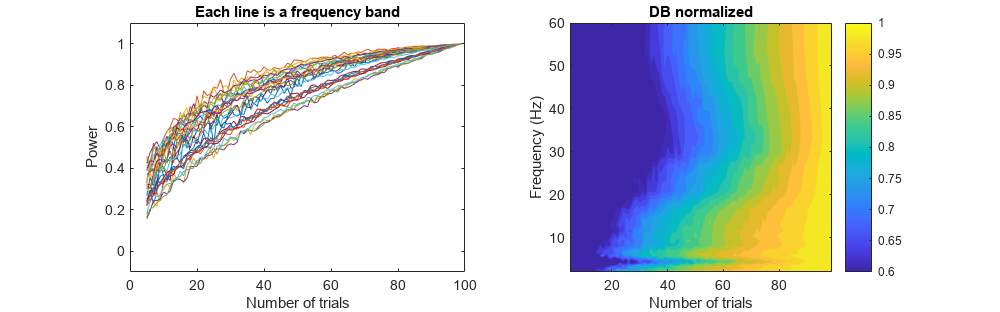

iterations=100;
chan2plot = 'P7';
dbcorrect = true;

powerByTrialFreq = zeros(length(frequencies),EEG.trials);

start_time = -200;
end_time   = 1200;

fft_data = fft(reshape(EEG.data(strcmpi(chan2plot,{EEG.chanlocs.labels}),:,:),1,[]),n_conv_pow2);
timeidx = dsearchn(EEG.times',[start_time end_time]');

for fi=1:length(frequencies)
    
    wavelet = exp(2*1i*pi*frequencies(fi).*time) .* exp(-time.^2./(2*( wavelet_cycles /(2*pi*frequencies(fi)))^2))/frequencies(fi);
    fft_wavelet = fft(wavelet,n_conv_pow2);
    
    convolution_result = ifft(fft_wavelet.*fft_data,n_conv_pow2) * sqrt(wavelet_cycles /(2*pi*frequencies(fi)));
    convolution_result = convolution_result(1:n_convolution);
    convolution_result = convolution_result(half_of_wavelet_size+1:end-half_of_wavelet_size);
    convolution_result = abs(reshape(convolution_result,EEG.pnts,EEG.trials)).^2; % reshape and convert to power
    
    if dbcorrect
        template = 10*log10( bsxfun(@rdivide,mean(convolution_result,2),mean(mean(convolution_result(baselineidx(1):baselineidx(2),:),1),2)));
        template = template(timeidx(1):timeidx(2));
    else
        template = mean(convolution_result(timeidx(1):timeidx(2),:),2);
    end
    template = bsxfun(@rdivide,bsxfun(@minus,template,mean(template)),std(template))';
    
    for iteri=1:iterations
        for triali=5:EEG.trials
            
            trials2use = randsample(1:EEG.trials,triali);
            
            if dbcorrect
                tempdat = 10*log10( bsxfun(@rdivide,mean(convolution_result(:,trials2use),2),mean(mean(convolution_result(baselineidx(1):baselineidx(2),trials2use),1),2)));
                tempdat = tempdat(timeidx(1):timeidx(2));
            else
                tempdat = mean(convolution_result(timeidx(1):timeidx(2),trials2use),2);
            end
            tempdat = bsxfun(@rdivide,bsxfun(@minus,tempdat,mean(tempdat)),std(tempdat))';
            
            powerByTrialFreq(fi,triali) = powerByTrialFreq(fi,triali) + (tempdat*tempdat')\tempdat*template';
        end
    end
end

powerByTrialFreq = powerByTrialFreq./iterations;


figure(Position=[100,100,800,250])

subplot(121)
plot(5:EEG.trials,squeeze(powerByTrialFreq(:,5:end)))
xlabel('Number of trials'), ylabel('Power')
set(gca,'ylim',[-.1 1.1])
title('Each line is a frequency band')

subplot(122)
contourf(5:EEG.trials,frequencies,squeeze(powerByTrialFreq(:,5:end)),40,'linecolor','none')
colorbar
set(gca,'clim',[.6 1])
xlabel('Number of trials'), ylabel('Frequency (Hz)')
if dbcorrect, title('DB normalized'), else title('not dB normalized'); end

**Figure 18.13**

*To examine how many trials is a reasonable minimum for each condition and frequency band, the average power time course of a randomly selected number of trials can be correlated with the average power time course of all trials.*

Based on other measures of reliability (such as Cronbach ’ s α , for example), trial counts that correspond to correlations of around 0.7 should provide a reasonable number of trials per condition.

## 18.14 Downsampling Results after Analyses

There is a distinction between precision and resolution. The high temporal resolution of EEG is necessary to apply time-frequency decomposition methods. However, after time-frequency decomposition, the temporal precision decreases because the estimate of power at each time point is a weighted combination of temporally surrounding time points. This means that activity from neighboring time points is autocorrelated and thus provides redundant information. In other words, after time-frequency decomposition, the temporal resolution is greater than the temporal precision. Thus, you can often downsample the results after the time-frequency decomposition with little or no loss of information. In many cases the results can be downsampled to 40 or 50 Hz. Downsampling the results will decrease computation time, decrease file read/write time, and decrease disk space usage. Whether and how much you should downsample the results depends on the analyses you plan on performing.

## 18.15 Describing This Analysis in Your Methods Section

Whether and how you compute baseline normalization is a small but critical detail of the Methods. Make sure you write which transform you used and the time period used for baseline activity. If no baseline normalization was applied, state whether any transformations were applied to the data, such as computing the logarithm of the power, prior to statistical analyses and plotting. Furthermore, you should justify the reason for applying or not applying baseline normalization.